# Walkthrough with SCC dataset

## Load the Data

addpath('./data')
load('SCC_dataset.mat')

## Process data and select features

Remove low-quality cells and select features:

- filter cells don't express min_exp percentage of genes

- select top #gene_selected informative genes

min_exp = 0.95; gene_selected = 3000;
[prodata,progene_name,procell_label] = preprocessing(data,gene_name,true_label,min_exp, ...
gene_selected);

## **Consensus clustering**

If choosing SC3 package to do the consensus clustering on the processed data, we can get the following cell-cell similarity matrix M: 

M = csvread('SCC_cell-cell.csv');

## **Number of clusters**

The number of clusters is estimated by analyzing the largest gap of sorted eigenvalues of symmetric normalized graph Laplacian:

Number of cluster based on zero eigenvalues & Largest gap 
     1     4



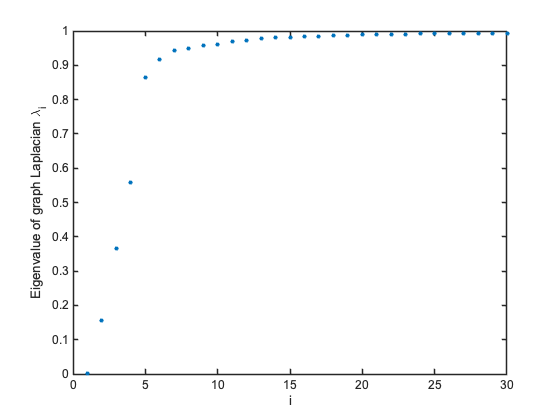

[eigenvalues] = plot_eigen_gap(M);

No_cluster = 4; 

## **Run QuanTC**

- **Soft clustering**: get the likelihoods of cells belonging to each cluster based on symmetric non-negative matrix factorization of M

- **CPI**: compute CPI value of each cell, use TC_cut to select cell with higher CPI values to be TC 

TC_cut = 0.34;
[result] = run_QuanTC(prodata,M,No_cluster,TC_cut);

- **2d-visualization**: cells are visualized through the probabilistic regularized embedding (PRE) approach

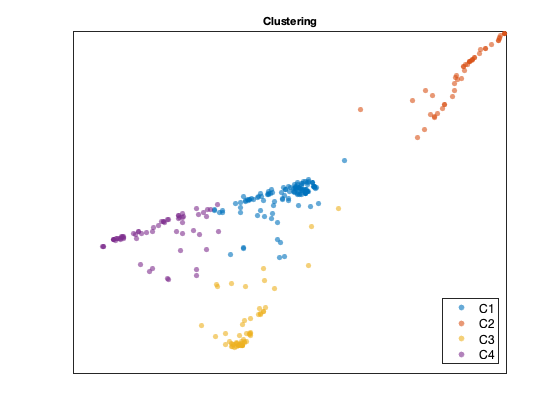

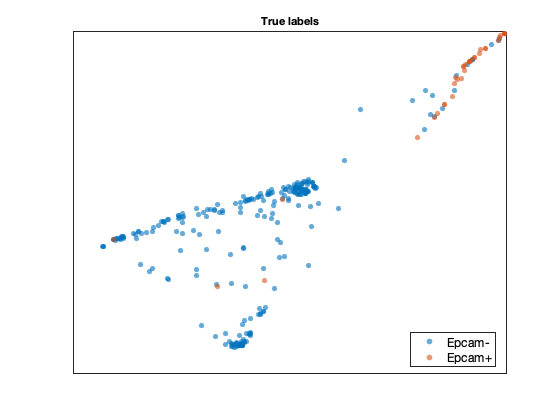

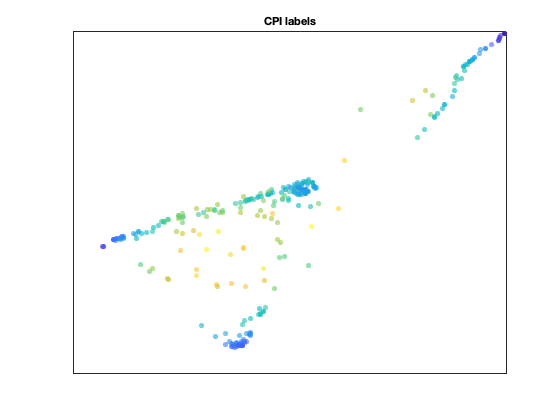

label_legend =  {'Epcam-','Epcam+'};
cell_visu_PRE(result,procell_label, label_legend)

## **Feature plot**

visualizes feature expressions on PRE

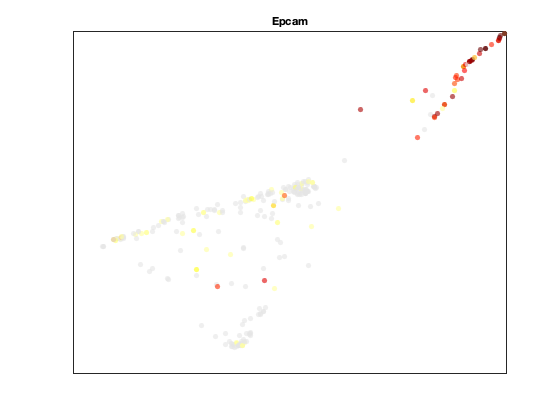

gene_plot = {'Epcam'};
featureplot(result,prodata,progene_name,gene_plot)

## **Transition trajectory**

- **Start/ end cluster**: choose non-ICS based on the percentage of TC associated with each cluster relative to the total number of TC

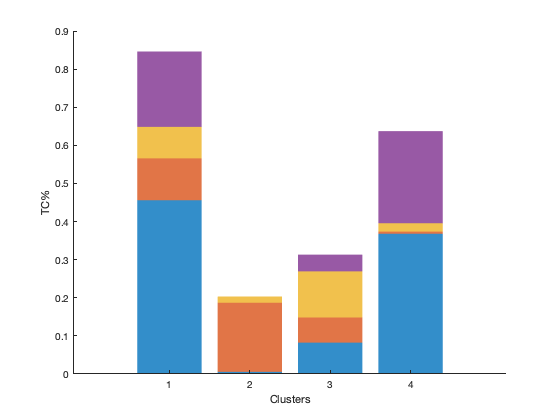

pTC(result,No_cluster)

- **Potential transition trajectories**: list the percetage of cells over whole cell population to choose the potential transition trajectories

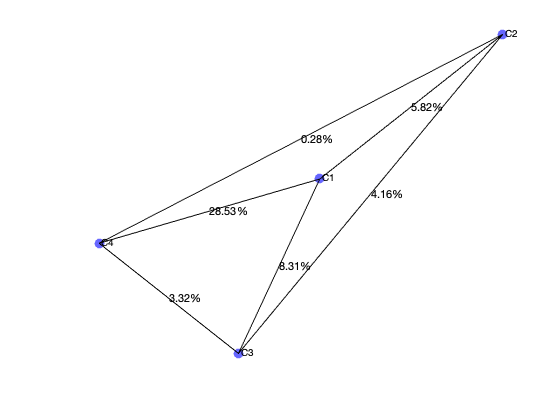

trajectory: 2  1  3  4, percentage of cells involved: 0.50693
trajectory: 2  1  4, percentage of cells involved: 0.65651
trajectory: 2  3  1  4, percentage of cells involved: 0.84211
trajectory: 2  3  4, percentage of cells involved: 0.26039
trajectory: 2  4, percentage of cells involved: 0.1385


start_cluster = 2; %choose starting cluster based on the above graph
%plot TC% between clusters among all the cells
[path,ordered_cell] = traj(result,start_cluster,No_cluster); 

## **Finding cluster marker genes and the transition genes that mark transition from one trajectory**

lam2 = 10;
[marker_gene,transition_gene] = markers(result,prodata,M,path{1},ordered_cell{1},lam2)

ans = 0.9783

Consistency of clustering: 0.97835


marker_gene = 4×1 cell array
    {  79×1 double}
    { 267×1 double}
    { 940×1 double}
    {1030×1 double}


transition_gene = 3×2 cell array
    {9×1 double}    {78×1 double}
    {4×1 double}    { 0×1 double}
    {[    2257]}    { 0×1 double}


## **Heatmap**

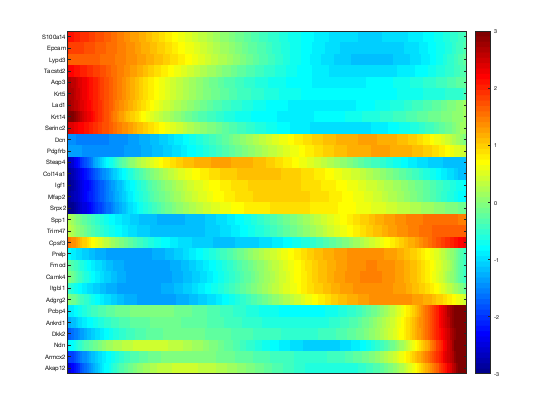

a = 5; b = 3; %plot top a marker genes and top 2b transition genes
[gene_plot,gene_cluster] = heatmap(prodata,marker_gene,transition_gene,path{1}, ...
ordered_cell{1},progene_name,a,b);

## **Plot transition genes along the transiton trajectory**

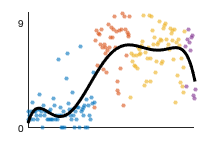

trans_gene_plot = transition_gene{1,1}(1);
tran_gene_plot(result,prodata,trans_gene_plot,path{1},ordered_cell{1},progene_name)

## **Get global pseudotime of the top2 trajectories**

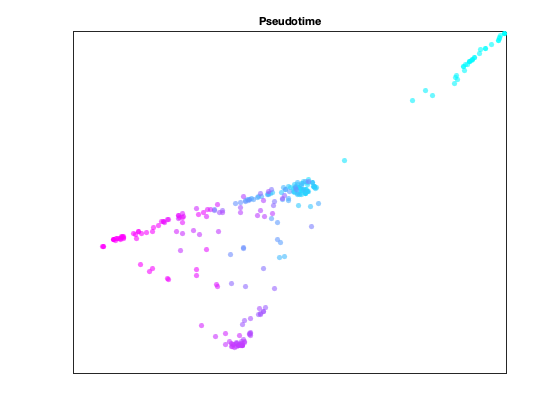

[global_ordered_cell,global_pseudotime_ordered] = global_pseudotime(result,[1,2],path,ordered_cell);

## **Get global pseudotime of all the cells based on one chosen trajectory**

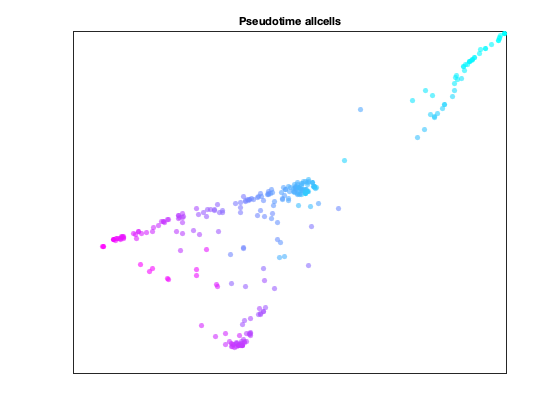

[pseudotime_allcells] = global_pseudotime_allcells(result,1,path,ordered_cell);